clear all;close all;

% 定義檔案路徑與檔名
basePath = 'C:\Users\sgrc-325\Desktop\git\pipes\data\p test\';
fileNames = {
    '1217_3P.CSV', ...
    '1217_4P.CSV', ...
    '1217_5P.CSV', ...
    '1217_6P.CSV', ...
    '1217_7P.CSV', ...
    '1217_8P.CSV', ...
    '1217_9P.CSV', ...
    '1217_10P.CSV', ...
    '1217_11P.CSV', ...
    '1217_12P.CSV', ...
    '1217_13P.CSV', ...
    '1217_14P.CSV', ...
    '1217_15P.CSV', ...
    '1217_16P.CSV'
    };

% 初始化儲存所有資料的表格
allData = [];

% 逐一讀取檔案並合併
for i = 1:length(fileNames)
    filePath = fullfile(basePath, fileNames{i});
    tempData = readtable(filePath, 'Delimiter', ',', 'ReadVariableNames', false);
    allData = [allData; tempData]; % 將每個表格資料合併
end

moData=allData;
mo=[moData.Var1 moData.Var1 moData.Var1 moData.Var4 moData.Var5 moData.Var6 moData.Var7 moData.Var8 moData.Var9 moData.Var10 moData.Var11 moData.Var12 moData.Var13 moData.Var14 moData.Var15 moData.Var16 moData.Var17 moData.Var18 moData.Var19];

[No,~]=size(mo);

t= moData.Var1;
time_rtc=moData.Var2;
time_gps=moData.Var3;
m = mo(:,4:6);
acc1 = mo(:,7:9);
gyr1=mo(:,10:12);
lat=mo(:,13);
lon=mo(:,14);
sats=mo(:,15);
fix=mo(:,16);
hacc=mo(:,17);
vacc=mo(:,18);
tem=mo(:,19);

ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
gx1=gyr1(:,1);gy1=gyr1(:,2);gz1=gyr1(:,3);
mx=m(:,1);my=m(:,2);mz=m(:,3);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2);
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差

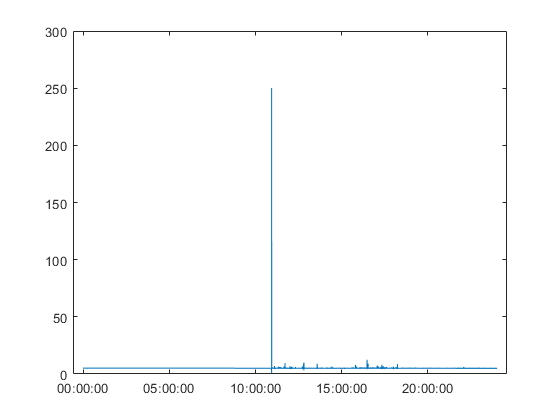

close all
tt = time_rtc;
% time_axis = time_gps;

figure(1)
plot(tt,GG)

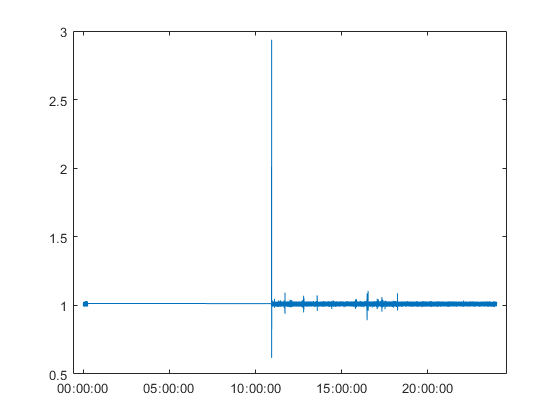

figure(2)
plot(tt,aG)

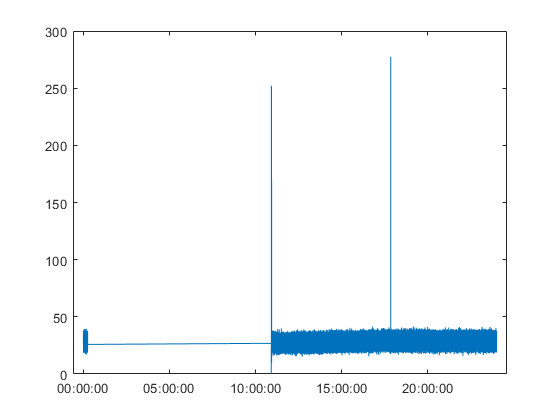


figure(2)
plot(tt,mm4)

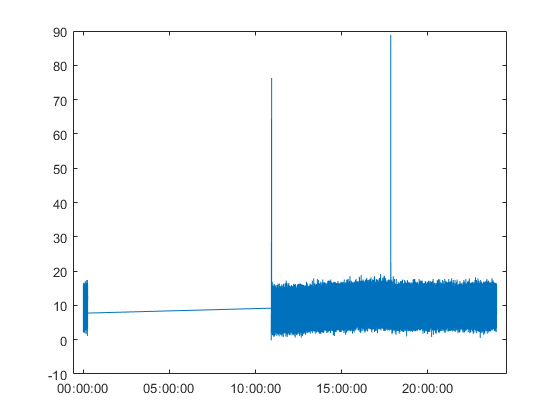


figure(4)
plot(tt,m(:,1))

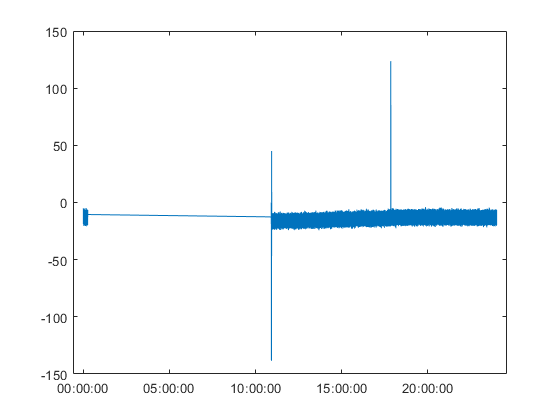

figure(5)
plot(tt,m(:,2))

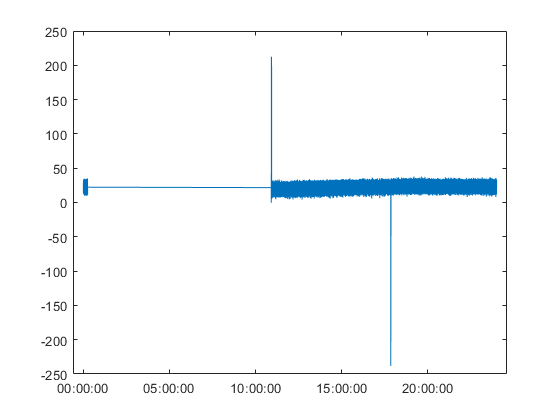

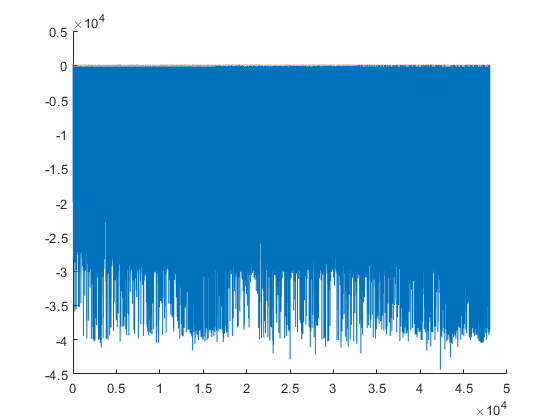

figure(6)
plot(tt,m(:,3))